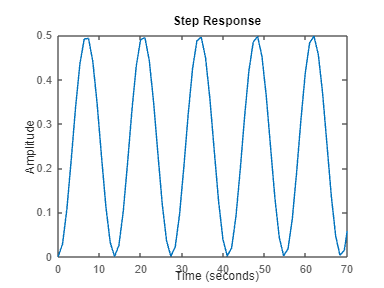

clc;
clear ;
close all;
m = 0.111;
R = 0.015;
g = -9.8;
L = 1.0;
d = 0.03;
J = 9.99e-6;
s = tf('s');
P_ball = -m*g*d/L/(J/R^2+m)/s^2;

Kp = 1;
C = pid(Kp);
sys_cl=feedback(C*P_ball,1);
figure(1);
step(0.25*sys_cl)
axis([0 70 0 0.5])

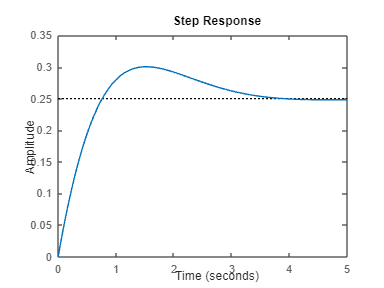

m = 0.111;
R = 0.015;
g = -9.8;
L = 1.0;
d = 0.03;
J = 9.99e-6;
s = tf('s');
P_ball = -m*g*d/L/(J/R^2+m)/s^2;

Kp = 10;
Kd = 10;
C = pid(Kp,0,Kd);

sys_cl=feedback(C*P_ball,1);
figure(2);
t=0:0.01:5;
step(0.25*sys_cl)

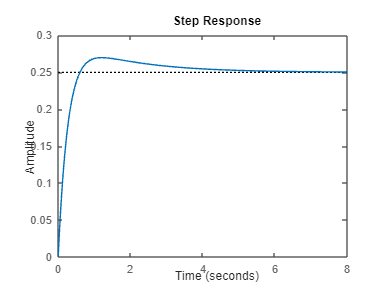

Kp = 10;
Kd = 20;
C = pid(Kp,0,Kd);
sys_cl=feedback(C*P_ball,1);
figure(3);
step(0.25*sys_cl)

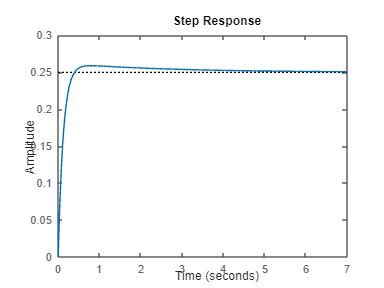

Kp = 15;
Kd = 40;
C = pid(Kp,0,Kd);
sys_cl=feedback(C*P_ball,1);
figure(4);
step(0.25*sys_cl)